# Figure 3G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A041_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(10*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(10*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(10*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .6;
        end
     

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

        S(i).cdkHighGate = cdkHighGate;

end

conds = [1 3 17];
f1 = figure; 
f2=figure;
hold on
ally = [];
groups = [];
barplot_values=[];
b=[];
std_b=[];
for i = 1:length(conds)
    crlAct = S(conds(i)).POI(:,3);
    mitosis = S(conds(i)).POI(:,1);
    nextmitosis = S(conds(i)).POI(:,6)-5;
    g2 = S(conds(i)).POI(:,5);
    cdk2 = S(conds(i)).cdk;
   
    if conds(i)==17
        inds = ~isnan(crlAct) & S(conds(i)).goodCdk &S(conds(i)).apcExpressGate & S(conds(i)).apcGate  ;% & (S(conds(i)).POI_realtime(:,3)-S(conds(i)).POI_realtime(:,1))>2& (S(conds(i)).POI_realtime(:,3)-S(conds(i)).POI_realtime(:,1))<5; 
    else

    inds = ~isnan(crlAct) & S(conds(i)).goodCdk &S(conds(i)).apcExpressGate  & S(conds(i)).apcGateAll  ;%& (S(conds(i)).POI_realtime(:,3)-S(conds(i)).POI_realtime(:,1))>2& (S(conds(i)).POI_realtime(:,3)-S(conds(i)).POI_realtime(:,1))<5;
    end
    sum (inds)

   crlAct = crlAct(inds,:);
    mitosis = mitosis(inds,:);
 nextmitosis =  nextmitosis(inds,:);
g2 = g2(inds,:);

    cdk2 = smoothdata(cdk2(inds,:),2,'movmedian',7);

    cdk_zero = NaN*ones([length(cdk2(:,1)),1]);

    for n = 1:size(crlAct,1)
       
        cdk_zero(n) =cdk2(n,crlAct(n));
      
    end
b(i) = mean (cdk_zero);
std_b(i) = (std(cdk_zero))/(sqrt(length(cdk_zero)));


ally = [ally; cdk_zero];
    groups = [groups; repmat(i,size(cdk_zero))];
end

ans = 491

ans = 226

ans = 194

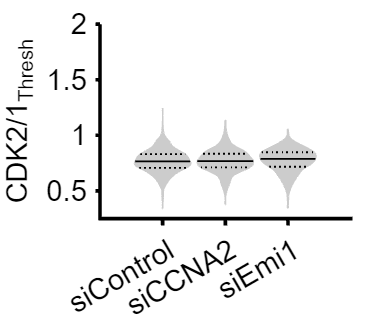




 hold on
violinPlot((ally),'groups',groups,'histOpt',1,'showMM',6,'divFactor',1,'widthDiv',[1 1]);

ylim([.25 2])
xticklabels({'siControl','siCCNA2','siEmi1'})
ylabel('CDK2/1_{Thresh}')



% print_pdf(['Fig3g.pdf'])

p1=mediantest(ally(groups==1),ally(groups==2))

p1 = 0.8524


p2=mediantest(ally(groups==1),ally(groups==3))

p2 = 0.0854